DOE optimisation code. Created by Thomas Dixon 04/04/2024

## **Step 1: **Set the design space limits (lower and upper bounds of each variable)

clear all
%                       [Voltage (V), Time (S), Conc (mg ml-1)]
variableBoundsModel =   [-4, 10, 0.01;       % LB
                         -1, 60, 0.05]       % UB

variableBoundsModel =    -4.0000   10.0000    0.0100
   -1.0000   60.0000    0.0500


numbOfVars = size(variableBoundsModel,2)

numbOfVars = 3

## **Step 2**: Define the parameters

experiments = readtable("ExperimentsRuhex3D.xlsx")

experiments = 11×5 table
    ExperimentNumber    Voltage_V    Time_S    Concentration_Mg_mL    Iruhex_nA
    ________________    _________    ______    ___________________    _________

            1               -4         60             0.05             -87.646 
            2               -4         60             0.05             -58.774 
            3               -4         60             0.05             -73.983 
            4               -4         60             0.01              -31.95 
            5               -4         10             0.01              -35.02 
            6               -4         10             0.05              -115.8 
            7               -1         10             0.01             -58.886 
            8               -1         10             0.05               -44.5 
    

experimentNumb = experiments{:,1};
experimentDesignSpaceModel = experiments{:,2:4}; %Paramters are in columns 2-4

## **Step 3:** Plot the design space

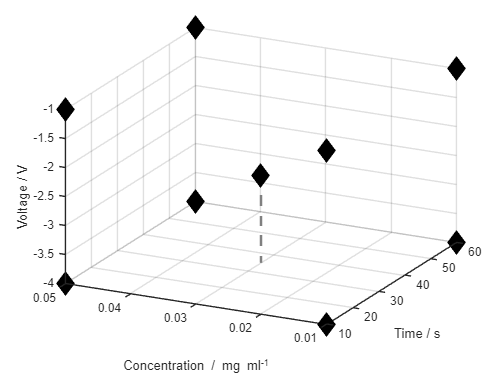

figure

scatter3(experimentDesignSpaceModel(:,2), experimentDesignSpaceModel(:,3), experimentDesignSpaceModel(:,1), 200, 'filled', "kd")
zlabel("Voltage / V")
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")

hold on
plot3([experimentDesignSpaceModel(end,2) experimentDesignSpaceModel(end,2)], [experimentDesignSpaceModel(end,3) experimentDesignSpaceModel(end,3)], [experimentDesignSpaceModel(end,1), -4], "Color","#808080","LineWidth",2, "LineStyle","--")
hold off

xlim([10, 60])

view([-63.61 27.65])

%colorbar

## **Step 4:** Set the response value (IRuhex) for each condition run

logged = false;

if logged
    responses = log(experiments{:,end}*-1); %Last column in csv file
else
    responses = experiments{:,end};
end

responsesNorm = experiments{:,end};

## **Step 5: **Plot desgin space with response

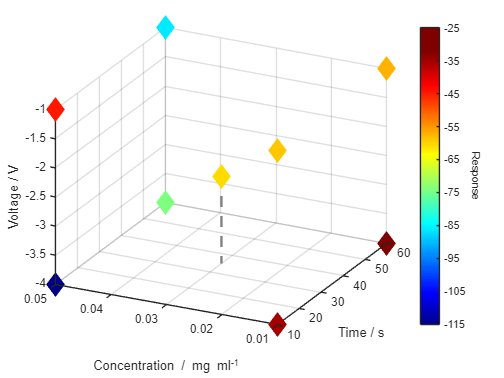

figure

scatter3(experimentDesignSpaceModel(:,2), experimentDesignSpaceModel(:,3), experimentDesignSpaceModel(:,1), 200, responsesNorm, "d", "filled")
hold on
plot3([experimentDesignSpaceModel(end,2) experimentDesignSpaceModel(end,2)], [experimentDesignSpaceModel(end,3) experimentDesignSpaceModel(end,3)], [experimentDesignSpaceModel(end,1), -4], "Color","#808080","LineWidth",2, "LineStyle","--")
hold off

colormap(jet)
zlabel("Voltage / V")
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")

h = colorbar;
h.Label.String = "Response";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";
h.Limits = [-115,-25];
set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar

xlim([10 60])

view([-63.61 27.65])

## **Step 6: **Fit model and plot different response surfaces

figure

model = 'interactions'

model = 'interactions'


[LB, UB] = bounds(experimentDesignSpaceModel,1);
normalisedResults = (experimentDesignSpaceModel - LB)./(UB-LB);

mdl = fitlm(normalisedResults, responses, model)

mdl = Linear regression model:
    y ~ 1 + x1*x2 + x1*x3 + x2*x3

Estimated Coefficients:
                   Estimate      SE        tStat       pValue 
                   ________    ______    _________    ________

    (Intercept)    -46.118     16.891      -2.7302     0.05243
    x1              -1.383     22.133    -0.062488     0.95317
    x2              25.553     22.133       1.1545     0.31256
    x3             -58.297     22.133       -2.634    0.057945
    x1:x2          -46.465     24.736      -1.8784     0.13353
    x1:x3             50.2     24.736       2.0294     0.11229
    x2:x3           1.6949     24.736     0.068519     0.94866


Number of observations: 11, Error degrees of freedom: 4
Root Mean Squared Error: 18.4

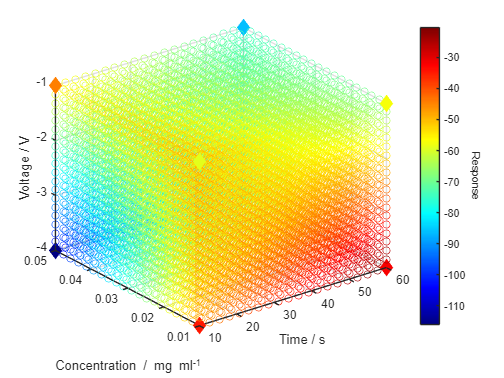


varInterval = 20;
for var = 1:numbOfVars
    spacing(:,var) = {linspace(variableBoundsModel(1,var), variableBoundsModel(2,var), varInterval)};
end

combs = permn(1:varInterval,numbOfVars);
for var = 1:numbOfVars
    gridSearch(:,var) = spacing{1,var}(combs(:,var));
end

gridSearchNorm = (gridSearch - LB)./(UB-LB);

matrixPred= predict(mdl, gridSearchNorm);

if logged
    matrixPred = exp(matrixPred)*-1;
end

scatter3(gridSearch(:,2), gridSearch(:,3), gridSearch(:,1), [], matrixPred)
hold on
scatter3(experimentDesignSpaceModel(:,2), experimentDesignSpaceModel(:,3), experimentDesignSpaceModel(:,1), 100, responsesNorm, "d", "filled")
hold off
colormap(jet)
zlabel("Voltage / V")
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")

xlim(variableBoundsModel(:,2)')

h = colorbar;
h.Label.String = "Response";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";

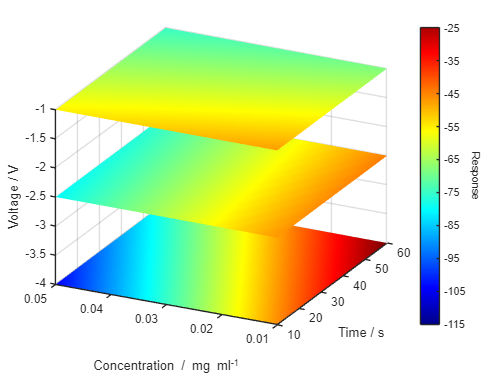

figure

[X,Y] = meshgrid(linspace(variableBoundsModel(1,2), variableBoundsModel(2,2), 100), linspace(variableBoundsModel(1,3), variableBoundsModel(2,3), 100));
Z = [-1, -2.5, -4];

for i = 1:length(Z)
    ZMesh(:,:,i) = ones(100,100).*Z(i);
end

Xnorm = (X - min(X, [], "all"))./(max(X, [], "all")-min(X, [], "all"));
Ynorm = (Y - min(Y, [], "all"))./(max(Y, [], "all")-min(Y, [], "all"));
Znorm = (Z - min(Z, [], "all"))./(max(Z, [], "all")-min(Z, [], "all"));
ZMeshNorm = (ZMesh - min(ZMesh, [], "all"))./(max(ZMesh, [], "all")-min(ZMesh, [], "all"));

coefs = mdl.Coefficients.Estimate;
surfResults = [];
for i = 1:length(Z)
    surfResults(:,:, i) = coefs(1) + (coefs(2).*ZMeshNorm(:,:,i)) + (coefs(3).*Xnorm) + (coefs(4).*Ynorm) + (coefs(5).*ZMeshNorm(:,:,i).*Xnorm) + (coefs(6).*ZMeshNorm(:,:,i).*Ynorm) + (coefs(7).*Xnorm.*Ynorm);
end

if logged
    surfResults = exp(surfResults)*-1;
end

scatter3(30*ones(1,length(responses)), 0.03*ones(1,length(responses)), -100*ones(length(responses),1),100, responsesNorm, "d", "filled")

hold on
surf(X, Y, ZMesh(:,:,1), surfResults(:,:, 1), "EdgeColor","texturemap")
surf(X, Y, ZMesh(:,:,2), surfResults(:,:, 2), "EdgeColor","texturemap")
surf(X, Y, ZMesh(:,:,3), surfResults(:,:, 3), "EdgeColor","texturemap")
hold off

colormap(jet)
zlabel("Voltage / V")
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")

h = colorbar;
h.Label.String = "Response";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";

set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar

xlim([variableBoundsModel(1,2), variableBoundsModel(2,2)])
ylim([variableBoundsModel(1,3), variableBoundsModel(2,3)])
zlim([variableBoundsModel(1,1), variableBoundsModel(2,1)])

h.Limits = [-115,-25];
set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar
view([-63.61 27.65])

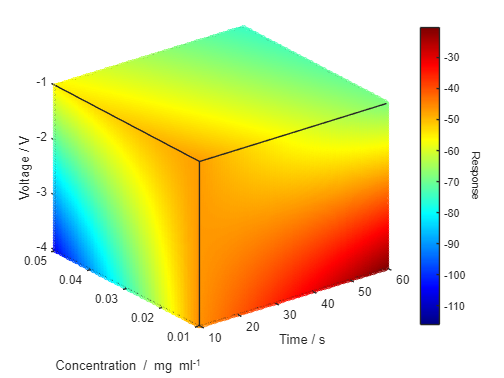

figure

intervals = 100;

%Voltage = Z, Time = X and Conc = Y
Xint = linspace(variableBoundsModel(1,2), variableBoundsModel(2,2), intervals);
Yint = linspace(variableBoundsModel(1,3), variableBoundsModel(2,3), intervals);
Zint = linspace(variableBoundsModel(1,1), variableBoundsModel(2,1), intervals);

[X,Y,Z] = meshgrid(Xint, Yint, Zint);

Xnorm = (X - min(X, [], "all"))./(max(X, [], "all")-min(X, [], "all"));
Ynorm = (Y - min(Y, [], "all"))./(max(Y, [], "all")-min(Y, [], "all"));
Znorm = (Z - min(Z, [], "all"))./(max(Z, [], "all")-min(Z, [], "all"));

coefs = mdl.Coefficients.Estimate;
surfResults= coefs(1) + (coefs(2).*Znorm) + (coefs(3).*Xnorm) + (coefs(4).*Ynorm) + (coefs(5).*Znorm.*Xnorm) + (coefs(6).*Znorm.*Ynorm) + (coefs(7).*Xnorm.*Ynorm);
% designSpaceArry = {X,Y,Z};
% allInt = [Xint; Yint; Zint]

if logged
    surfResults = exp(surfResults)*-1;
end

designSpaceArry = {Y,X,Z};
allInt = [Yint; Xint; Zint];

allData = [X(:), Y(:), Z(:), surfResults(:)];

dataPointRef = ones(length(responses),1)*-10;

scatter3(allData(:,1), allData(:,2), allData(:,3), 15, allData(:,4))

hold on
scatter3(dataPointRef,dataPointRef,dataPointRef,1,responsesNorm)
hold off

colormap(jet)
zlabel("Voltage / V")
xlabel("Time / s")
ylabel("Concentration / mg ml^{-1}")

h = colorbar;
h.Label.String = "Response";
h.Label.Rotation = 270;
h.Label.VerticalAlignment = "bottom";

xlim([variableBoundsModel(1,2), variableBoundsModel(2,2)])
ylim([variableBoundsModel(1,3), variableBoundsModel(2,3)])
zlim([variableBoundsModel(1,1), variableBoundsModel(2,1)])

box on
ax = gca;
ax.BoxStyle = 'full';

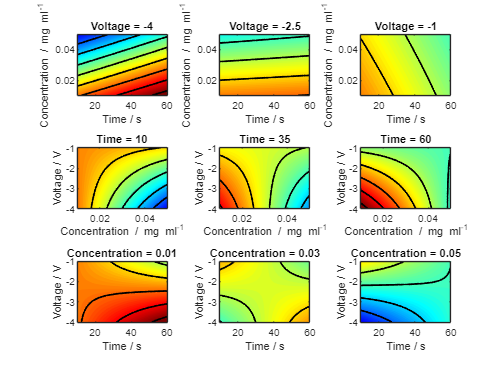

figure

xLayers = 1:3;
numbPlots = max(xLayers)*length(designSpaceArry);
allPoints = sort(repmat(1:3, 1, length(xLayers)))';
allPoints = [allPoints repmat(xLayers, 1, 3)'];

axisTitles = ["Concentration", "Time", "Voltage"];
axisUnits = [" / mg ml^{-1}", " / s", " / V"];

planes = [2,1,3;
          1,3,2;
          2,3,1];

for xi = 1:size(allPoints,1)
    subplot(3, length(xLayers),xi)
    p1 = allPoints(xi,1);
    p2 = allPoints(xi,2);

    p2x = round( ((p2 - min(xLayers)) / (max(xLayers) - min(xLayers)))*(intervals-1) + 1);

    indexs = {1:intervals, 1:intervals, 1:intervals};
    indexs{planes(p1, end)} = p2x;

    arry1 = permute(designSpaceArry{planes(p1, 1)}(indexs{:}), planes(p1,:));
    arry2 = permute(designSpaceArry{planes(p1, 2)}(indexs{:}), planes(p1,:));
    surfResultsPer =  permute(surfResults(indexs{:}), planes(p1,:));

    contourf(arry1, arry2,surfResultsPer,'LineColor','none', "LevelListMode","auto", 'LevelList', linspace(-115, -25, 100))
    hold on
    scatter([-10,-10], [-10,-10], 1, [-25, -115])
    contour(arry1, arry2,surfResultsPer,'LevelList', linspace(-115, -25, 10), 'LineColor', 'black', 'LineWidth', 1.5)
    hold off

    colormap(jet)

    xlabel(axisTitles(planes(p1, 1)) + axisUnits(planes(p1, 1)))
    ylabel(axisTitles(planes(p1, 2)) + axisUnits(planes(p1, 2)))
    title(axisTitles(planes(p1, 3)) + " = " + string(round(allInt(planes(p1, 3), p2x),2, "significant")))
    
%     h = colorbar;
%     h.Label.String = "Response";
%     h.Label.Rotation = 270;
%     h.Label.VerticalAlignment = "bottom";
% 
%     %set(h, 'TickDirection', 'both');
%     set(h, 'TickLength', 0.1); % Adjust the length of ticks as needed
%     set(h, 'Ticks', round(linspace(-115, -25, 10))); % Set the ticks on the color bar

    xlim([min(allInt(planes(p1, 1),:)), max(allInt(planes(p1, 1),:))])
    ylim([min(allInt(planes(p1, 2),:)), max(allInt(planes(p1, 2),:))])
end

This code finds the permitations, you can ignore this (i did not write it)

function [M, I] = permn(V, N, K)
% PERMN - permutations with repetition
%   Using two input variables V and N, M = PERMN(V,N) returns all
%   permutations of N elements taken from the vector V, with repetitions.
%   V can be any type of array (numbers, cells etc.) and M will be of the
%   same type as V.  If V is empty or N is 0, M will be empty.  M has the
%   size numel(V).^N-by-N. 
%
%   When only a subset of these permutations is needed, you can call PERMN
%   with 3 input variables: M = PERMN(V,N,K) returns only the K-ths
%   permutations.  The output is the same as M = PERMN(V,N) ; M = M(K,:),
%   but it avoids memory issues that may occur when there are too many
%   combinations.  This is particulary useful when you only need a few
%   permutations at a given time. If V or K is empty, or N is zero, M will
%   be empty. M has the size numel(K)-by-N. 
%
%   [M, I] = PERMN(...) also returns an index matrix I so that M = V(I).
%
%   Examples:
%     M = permn([1 2 3],2) % returns the 9-by-2 matrix:
%              1     1
%              1     2
%              1     3
%              2     1
%              2     2
%              2     3
%              3     1
%              3     2
%              3     3
%
%     M = permn([99 7],4) % returns the 16-by-4 matrix:
%              99     99    99    99
%              99     99    99     7
%              99     99     7    99
%              99     99     7     7
%              ...
%               7      7     7    99
%               7      7     7     7
%
%     M = permn({'hello!' 1:3},2) % returns the 4-by-2 cell array
%             'hello!'        'hello!'
%             'hello!'        [1x3 double]
%             [1x3 double]    'hello!'
%             [1x3 double]    [1x3 double]
%
%     V = 11:15, N = 3, K = [2 124 21 99]
%     M = permn(V, N, K) % returns the 4-by-3 matrix:
%     %        11  11  12
%     %        15  15  14
%     %        11  15  11
%     %        14  15  14
%     % which are the 2nd, 124th, 21st and 99th permutations
%     % Check with PERMN using two inputs
%     M2 = permn(V,N) ; isequal(M2(K,:),M)
%     % Note that M2 is a 125-by-3 matrix
%
%     % PERMN can be used generate a binary table, as in
%     B = permn([0 1],5)  
%
%   NB Matrix sizes increases exponentially at rate (n^N)*N.
%
%   See also PERMS, NCHOOSEK
%            ALLCOMB, PERMPOS, NEXTPERM, NCHOOSE2 on the File Exchange
% tested in Matlab 2018a
% version 6.2 (jan 2019)
% (c) Jos van der Geest
% Matlab File Exchange Author ID: 10584
% email: samelinoa@gmail.com
% History
% 1.1 updated help text
% 2.0 new faster algorithm
% 3.0 (aug 2006) implemented very fast algorithm
% 3.1 (may 2007) Improved algorithm Roger Stafford pointed out that for some values, the floor
%   operation on floating points, according to the IEEE 754 standard, could return
%   erroneous values. His excellent solution was to add (1/2) to the values
%   of A.
% 3.2 (may 2007) changed help and error messages slightly
% 4.0 (may 2008) again a faster implementation, based on ALLCOMB, suggested on the
%   newsgroup comp.soft-sys.matlab on May 7th 2008 by "Helper". It was
%   pointed out that COMBN(V,N) equals ALLCOMB(V,V,V...) (V repeated N
%   times), ALLCMOB being faster. Actually version 4 is an improvement
%   over version 1 ...
% 4.1 (jan 2010) removed call to FLIPLR, using refered indexing N:-1:1
%   (is faster, suggestion of Jan Simon, jan 2010), removed REPMAT, and
%   let NDGRID handle this
% 4.2 (apr 2011) corrrectly return a column vector for N = 1 (error pointed
%    out by Wilson).
% 4.3 (apr 2013) make a reference to COMBNSUB
% 5.0 (may 2015) NAME CHANGED (COMBN -> PERMN) and updated description,
%   following comment by Stephen Obeldick that this function is misnamed
%   as it produces permutations with repetitions rather then combinations.
% 5.1 (may 2015) always calculate M via indices
% 6.0 (may 2015) merged the functionaly of permnsub (aka combnsub) and this
%   function
% 6.1 (may 2016) fixed spelling errors
% 6.2 (jan 2019) fixed some coding style warnings
narginchk(2, 3) ;
if fix(N) ~= N || N < 0 || numel(N) ~= 1
    error('permn:negativeN','Second argument should be a positive integer') ;
end
nV = numel(V) ;
if nargin==2 
    %% PERMN(V,N) - return all permutations
    if nV == 0 || N == 0
        M = zeros(nV, N) ;
        I = zeros(nV, N) ;
    elseif N == 1
        % return column vectors
        M = V(:) ;
        I = (1:nV).' ;
    else
        % this is faster than the math trick used with 3 inputs below
        [Y{N:-1:1}] = ndgrid(1:nV) ;
        I = reshape(cat(N+1, Y{:}), [], N) ;
        M = V(I) ;
    end
else
    %% PERMN(V,N,K) - return a subset of all permutations
    nK = numel(K) ;
    if nV == 0 || N == 0 || nK == 0
        M = zeros(numel(K), N) ;
        I = zeros(numel(K), N) ;
    elseif nK < 1 || any(K<1) || any(K ~= fix(K))
        error('permn:InvalidIndex','Third argument should contain positive integers.') ;
    else
        V = reshape(V, 1, []) ; % v1.1 make input a row vector
        nV = numel(V) ;
        Npos = nV^N ;
        if any(K > Npos)
            warning('permn:IndexOverflow', ...
                'Values of K exceeding the total number of combinations are saturated.')
            K = min(K, Npos) ;
        end
             
        % The engine is based on version 3.2 with the correction
        % suggested by Roger Stafford. This approach uses a single matrix
        % multiplication.
        B = nV.^(1-N:0) ;
        I = ((K(:)-.5) * B) ; % matrix multiplication
        I = rem(floor(I), nV) + 1 ;
        M = V(I) ;
    end
end
% Algorithm using for-loops
% which can be implemented in C or VB
%
% nv = length(V) ;
% C = zeros(nv^N,N) ; % declaration
% for ii=1:N,
%     cc = 1 ;
%     for jj=1:(nv^(ii-1)),
%         for kk=1:nv,
%             for mm=1:(nv^(N-ii)),
%                 C(cc,ii) = V(kk) ;
%                 cc = cc + 1 ;
%             end
%         end
%     end
% end


end
